## plot distribution of variables at different parameters

### Scatter figures for each variable

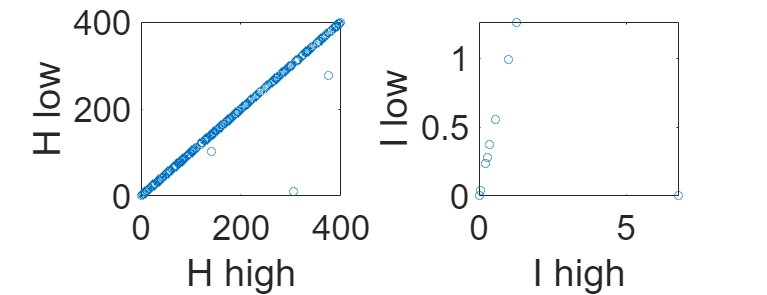

multi_ss = importdata('merged_multi_ss_488.txt');
tf = false(length(multi_ss), 1);
for i = 1:length(multi_ss)
if multi_ss(i, 2) == 0
tf(i) = true;
end
end
multi_ss(tf, :) = [];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% plot figures
figure;
xSize = 20; X=xSize; ySize = 7;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(1,2,1); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 3), multi_ss(:, 4)); hold on;
xlabel('H high'); ylabel('H low');
hold on;

subplot(1,2,2); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 5), multi_ss(:, 6)); hold on;
xlabel('I high'); ylabel('I low');
hold off;

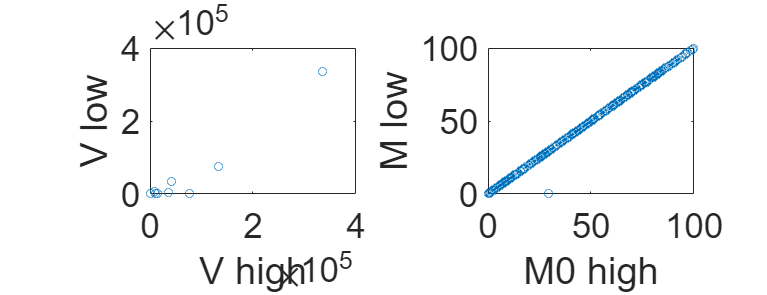


% plot figures
figure;
xSize = 20; X=xSize; ySize = 7;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(1,2,1); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 7), multi_ss(:, 8)); hold on;
xlabel('V high'); ylabel('V low');
hold on;

subplot(1,2,2); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 9) + multi_ss(:, 11), multi_ss(:, 10) +multi_ss(:, 12)); hold on;
xlabel('M0 high'); ylabel('M low');
hold off;

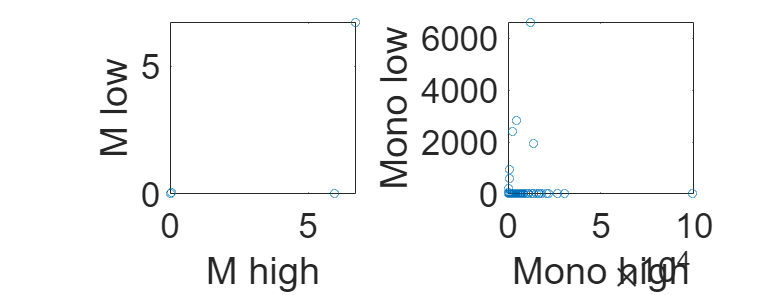


% plot figures
figure;
xSize = 20; X=xSize; ySize = 7;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(1,2,1); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 11), multi_ss(:, 12)); hold on;
xlabel('M high'); ylabel('M low');
hold on;

subplot(1,2,2); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 13), multi_ss(:, 14)); hold on;
xlabel('Mono high'); ylabel('Mono low');
hold off;

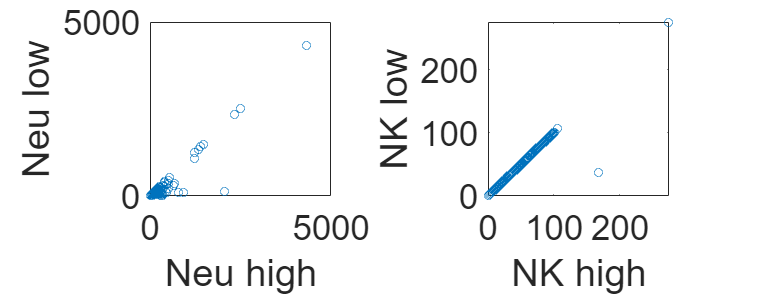


% plot figures
figure;
xSize = 20; X=xSize; ySize = 7;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(1,2,1); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 15), multi_ss(:, 16)); hold on;
xlabel('Neu high'); ylabel('Neu low');
hold on;

subplot(1,2,2); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 25), multi_ss(:, 26)); hold on;
xlabel('NK high'); ylabel('NK low');
hold off;

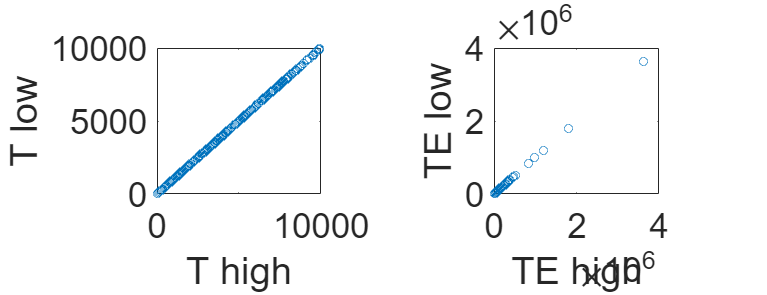


% plot figures
figure;
xSize = 20; X=xSize; ySize = 7;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(1,2,1); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 27), multi_ss(:, 28)); hold on;
xlabel('T high'); ylabel('T low');
hold on;

subplot(1,2,2); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 29), multi_ss(:, 30)); hold on;
xlabel('TE high'); ylabel('TE low');
hold off;

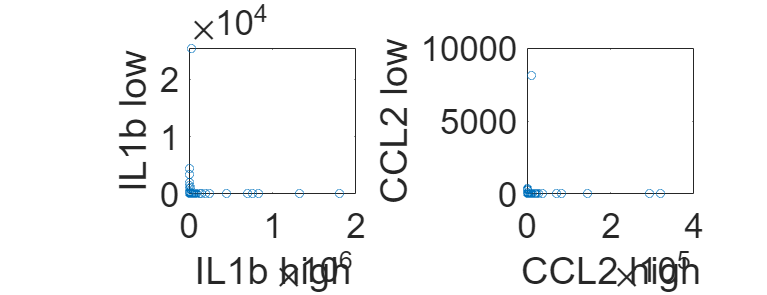


% plot figures
figure;
xSize = 20; X=xSize; ySize = 7;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(1,2,1); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 17), multi_ss(:, 18)); hold on;
xlabel('IL1b high'); ylabel('IL1b low');
hold on;

subplot(1,2,2); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 21), multi_ss(:, 22)); hold on;
xlabel('CCL2 high'); ylabel('CCL2 low');
hold off;

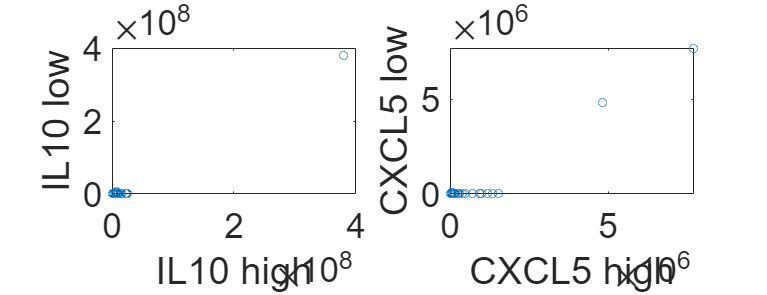


% plot figures
figure;
xSize = 20; X=xSize; ySize = 7;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(1,2,1); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 19), multi_ss(:, 20)); hold on;
xlabel('IL10 high'); ylabel('IL10 low');
hold on;

subplot(1,2,2); hold on; set(gca,'Fontsize',26); box on;
scatter(multi_ss(:, 23), multi_ss(:, 24)); hold on;
xlabel('CXCL5 high'); ylabel('CXCL5 low');
hold off;

### Parameter set number of bistable states for each variable

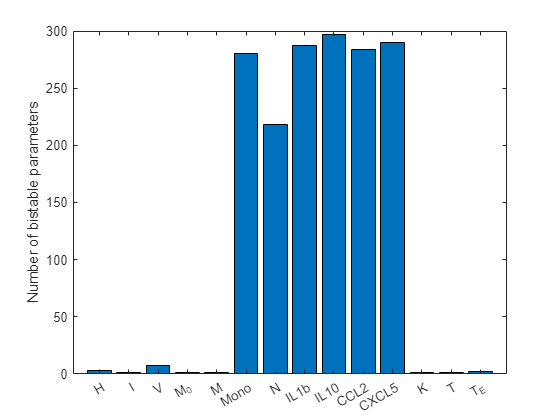

multi_ss = importdata('merged_multi_ss_488.txt');
tf = false(length(multi_ss), 1);
for i = 1:length(multi_ss)
if multi_ss(i, 2) == 0
tf(i) = true;
end
end
multi_ss(tf, :) = [];

ss_num = zeros(14, 1);

for i = 1:14
    diff_idx = multi_ss(multi_ss(:, 2 * i + 1) ~= multi_ss(:, 2 * i + 2));
    ss_num(i) = length(diff_idx);
end

figure;
var_name = categorical({'H', 'I', 'V', 'M_0', 'M', 'Mono', 'N', 'IL1b', 'IL10', 'CCL2', 'CXCL5', 'K', 'T', 'T_E'});
var_name = reordercats(var_name, {'H', 'I', 'V', 'M_0', 'M', 'Mono', 'N', 'IL1b', 'IL10', 'CCL2', 'CXCL5', 'K', 'T', 'T_E'});
bar(var_name, ss_num);
ylabel('Number of bistable parameters');

### Steady state distribution for variables

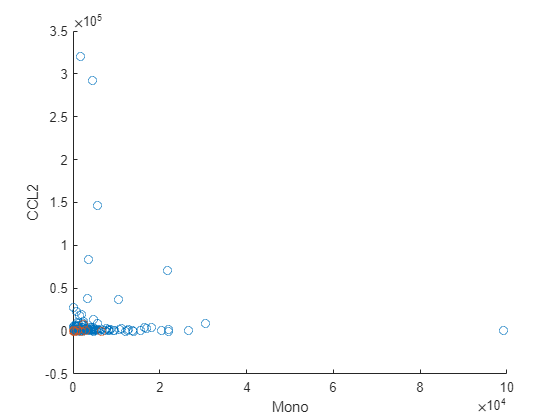

figure; hold on;
scatter(multi_ss(:, 13), multi_ss(:, 21));
scatter(multi_ss(:, 14), multi_ss(:, 22)); 
xlabel('Mono'); ylabel('CCL2');
hold off;

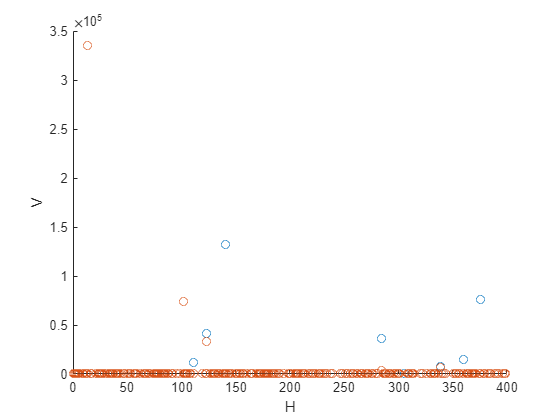

figure;
scatter(multi_ss(:, 3), multi_ss(:, 7)); hold on;
scatter(multi_ss(:, 4), multi_ss(:, 8));
xlabel('H'); ylabel('V');
hold off;

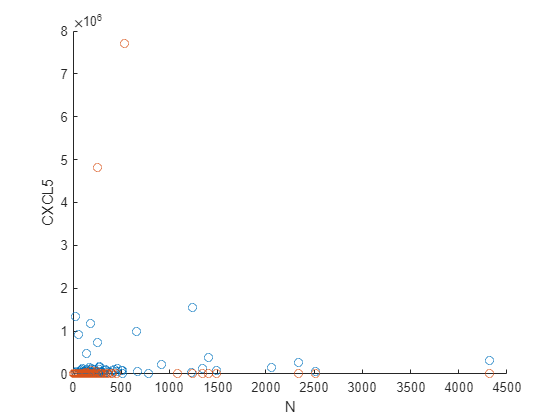

figure;
scatter(multi_ss(:, 15), multi_ss(:, 23)); hold on;
scatter(multi_ss(:, 16), multi_ss(:, 24)); 
xlabel('N'); ylabel('CXCL5');
hold off;

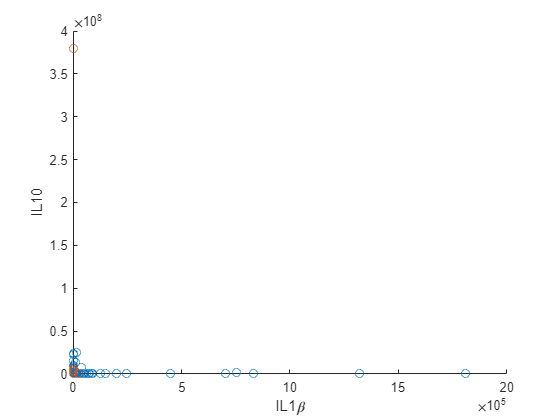

figure;
scatter(multi_ss(:, 17), multi_ss(:, 19)); hold on;
scatter(multi_ss(:, 18), multi_ss(:, 20)); 
xlabel('IL1\beta'); ylabel('IL10');
hold off;

### Bistable parameters distribution for single variable

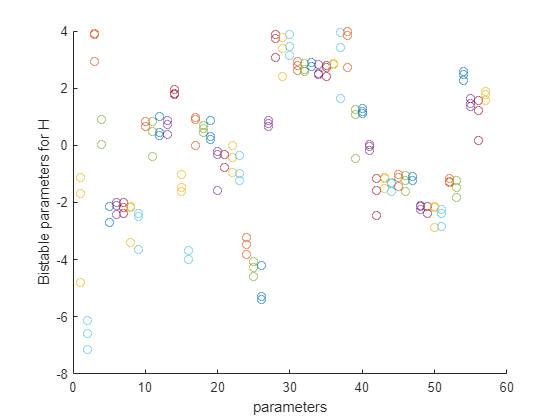

par_set_488 = importdata('multi_ss_par_488.txt');
log_par_ind = 1:57;
for i = log_par_ind
    par_set_488(:, i) = log10(par_set_488(:, i));
end
diff_idx_H = multi_ss(multi_ss(:, 3) ~= multi_ss(:, 4), 1);
figure;
for i = 1:size(par_set_488, 2)
    scatter(i .* ones(length(diff_idx_H)), par_set_488(diff_idx_H, i)); hold on;
end
xlabel('Parameters index'); ylabel('Bistable parameters for H');
hold off;

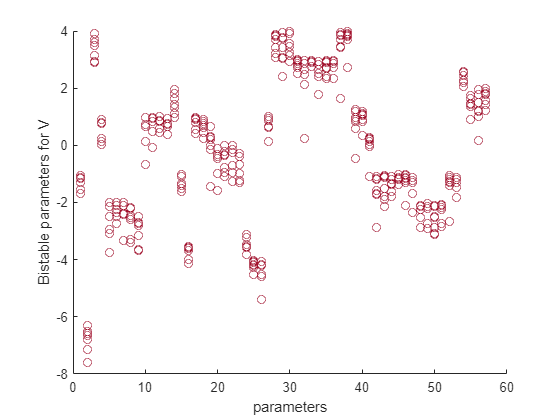

diff_idx_V = multi_ss(multi_ss(:, 7) ~= multi_ss(:, 8), 1);
figure;
for i = 1:size(par_set_488, 2)
    scatter(i .* ones(length(diff_idx_V)), par_set_488(diff_idx_V, i)); hold on;
end
xlabel('Parameters index'); ylabel('Bistable parameters for V');
hold off;

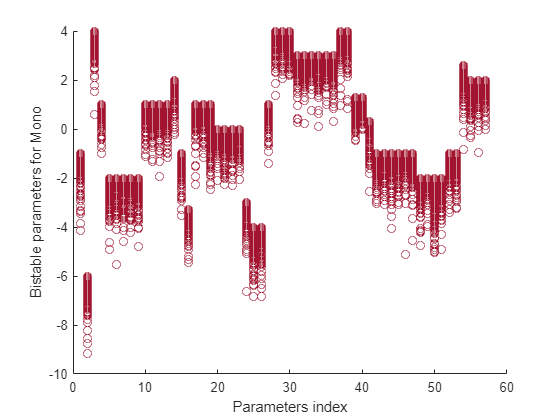

diff_idx_Mono = multi_ss(multi_ss(:, 13) ~= multi_ss(:, 14), 1);
figure;
for i = 1:size(par_set_488, 2)
    scatter(i .* ones(length(diff_idx_Mono)), par_set_488(diff_idx_Mono, i)); hold on;
end
xlabel('Parameters index'); ylabel('Bistable parameters for Mono');
hold off;

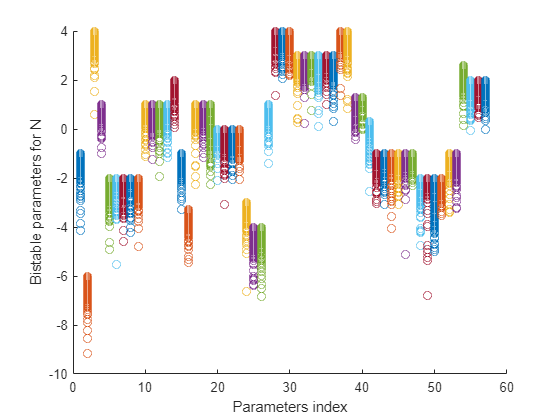

diff_idx_N = multi_ss(multi_ss(:, 15) ~= multi_ss(:, 16), 1);
figure;
for i = 1:size(par_set_488, 2)
    scatter(i .* ones(length(diff_idx_N)), par_set_488(diff_idx_N, i)); hold on;
end
xlabel('Parameters index'); ylabel('Bistable parameters for N');
hold off;